% Loading data from the experimental test

load TF_Motor.mat x
load TF_Motor.mat y

% Defining the transfer function constants 

K = 1

K = 1

Out = 0.63*K

Out = 0.6300

tau = 0.03 - 0.0205

tau = 0.0095

Te=5/1000;
%Designing the controller
w = 5/0.1   

w = 50


Ki=(tau*w^2)/(K)

Ki = 23.7500

Kp=(2*tau*w-1)/(K)

Kp = -0.0500

    
%sys = tf([10*K],[tau 1],'InputDelay',0.0205)
sys = tf([K],[tau 1])

sys =
 
       1
  ------------
  0.0095 s + 1
 
Continuous-time transfer function.



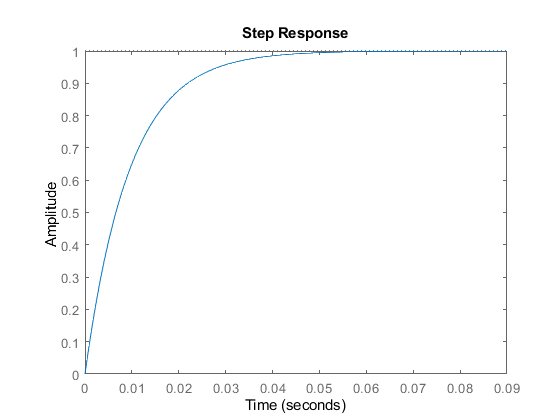

step(sys);


% Discretizing the controller
Cd = c2d(pid(Kp,Ki),Te,'zoh')  

Cd =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = -0.05, Ki = 23.7, Ts = 0.005
 
Sample time: 0.005 seconds
Discrete-time PI controller in parallel form.



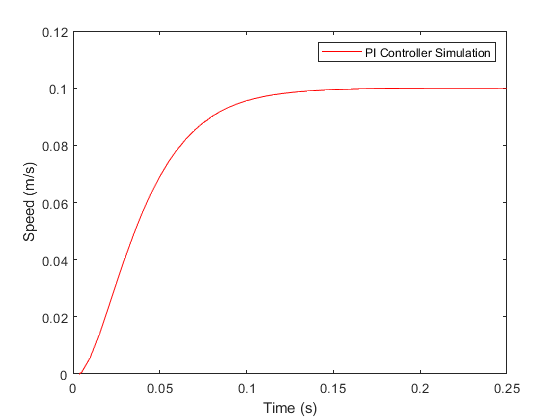


%Test Simulink
X_sim = out.stepsimulated.Data;
t1 = out.stepsimulated.Time;

X_pi = out.stepPI.Data;

X_real = out.stepreal.Data;
t2 = out.stepreal.Time;

% plot(t1, X_sim,'r', t2,X_real, 'b')
% xlabel('Time (s)') 
% ylabel('Speed (m/s)') 
% legend("Simulation",'Test data')
% xlim([0 0.25])

plot(t1, X_pi,'r')
xlabel('Time (s)') 
ylabel('Speed (m/s)') 
legend("PI Controller Simulation")
xlim([0 0.25])
ylim([0 0.12])